## Overview

This is some text

First we're going to look at the FFT of a wide and narrow spikes

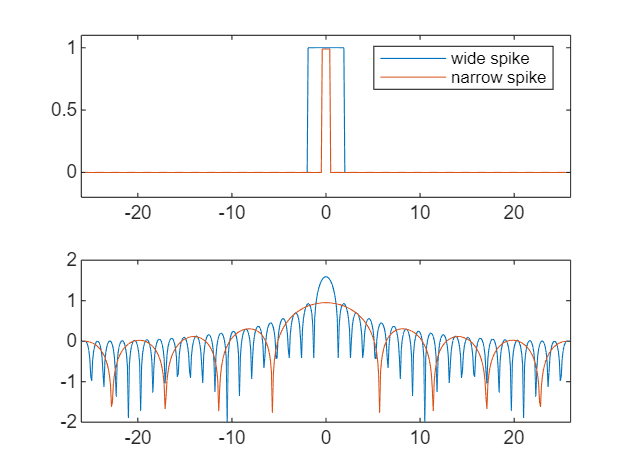

% MATLAB
sizeS=512;
x = -25.6:0.1:25.5;
y = zeros(2, sizeS) + 1e-15;
y(1,(abs(x)<2.0)) = 1.0;
y(2,(abs(x)<0.5)) = 0.99;
figure
subplot(2,1,1)
plot(x,y)
xlim([-26,26])
ylim([-0.2,1.1])
legend('wide spike','narrow spike');
subplot(2,1,2)
Hy = zeros(2,sizeS,'like',[0.0i]);
Hy(1,:) = fftshift(fft(ifftshift(y(1,:))));
Hy(2,:) = fftshift(fft(ifftshift(y(2,:))));
HyMAG = arrayfun(@(ii) log10(norm(ii)), Hy);
%HyMAG = arrayfun(@(ii) norm(ii), Hy);
plot(x, HyMAG)
xlim([-26,26])

## Explanation

Notice how

## Create Real Skymap and its interference pattern

now we'll create the skymap with some large and small dots ("stars")

dot=@(x,y,ss,r,cx,cy) (((repmat(0:ss:x,uint16(y/ss+1),1)-cx).^2+(repmat((0:ss:y)',1,uint16(x/ss+1))-cy).^2)<=r^2)*1.0

dot = function_handle with value:
    @(x,y,ss,r,cx,cy)(((repmat(0:ss:x,uint16(y/ss+1),1)-cx).^2+(repmat((0:ss:y)',1,uint16(x/ss+1))-cy).^2)<=r^2)*1.0


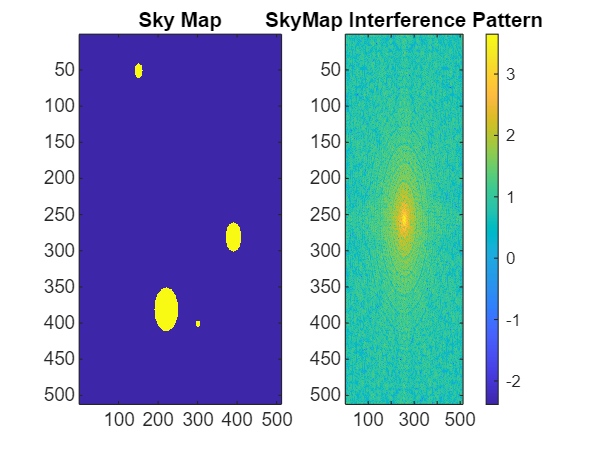


%SKYMAP DOTS
yy = dot(511,511,1, 10,150,50) + ...
     dot(511,511,1,5,300,400) + ...
     dot(511,511,1,30,220,380) + ...
     dot(511,511,1,20,390,280);

Hyy = fftshift(fft2(ifftshift(yy)));
HyyMAG = arrayfun(@(ii) log10(norm(ii)), Hyy);

figure()
subplot(1,2,1)
imagesc(yy)
title('Sky Map')

subplot(1,2,2)
imagesc(HyyMAG)
title('SkyMap Interference Pattern')
colorbar

See the plot

## Recover the real skymap from sampled interference pattern

%%
% MATLAB
rotMat = @(rot)[cosd(rot), -sind(rot); sind(rot), cosd(rot)];
rotate = @(rot,xy) int16(rotMat(rot)*xy');

r = [10,60,0.5,0.47; 30,80,0.55,0.5; 110,70,0.4,0.5; ...
     5,110,0.5,0.45; 20,60,0.5,0.5; 50,175,0.5,0.5; ...
     65,80,0.5,0.5; 20,60,0.5,0.5; 75,70,0.5,0.5; ...
     20,60,0.5,0.5; 50,175,0.5,0.5; 10,80,0.5,0.5; ...
     20,60,0.5,0.5];

t = 180;
sample = zeros(size(Hyy)) + 1e-15;
uvPoints = zeros(size(Hyy)) + 1e-15;

% ADD NOISE TO THE SAMPLED POINTS
% Generate log-normal distributed noise

% calculate the mean and standard deviation of the noise floor using bolzmann's equation and the system temperature
% T = 290 K
% B = 1 Hz
% k = 1.38064852e-23 J/K
% noise_floor = k * T / B
T = 300;
B = 1e6;
k = 1.38064852e-23;
noise_floor = k * T * B;
disp(['Temperature: ', num2str(T), ' K and Bandwidth: ', num2str(B), ' Hz']);
disp(['Noise floor: ', num2str(10*log10(noise_floor)), ' dB']);

Tsys = 3; %system noise in dB 
std = 3; % Standard deviation of the distribution in dB

noiseArray = 10.^(normrnd(10*log10(noise_floor)+Tsys, std, size(Hyy))/10);
sample = 10.^(normrnd(10*log10(noise_floor)+Tsys, std, size(Hyy))/10);

% First we create the skymap sampling pattern
for ll = r'
    for lll = arrayfun(@(t) rotate(ll(2)-t,[ll(1),0]), 0:t-1, 'UniformOutput', false)
        lll = lll{1};
        x = int16(lll(1)+length(Hyy(1,:))*ll(3));
        y = int16(lll(2)+length(Hyy(:,1))*ll(4));
        uvPoints(x,y) = 1.0;
        % Calculate the starting indices of the kernel
        start_x = x - floor(size(antenna_kernel, 1) / 2);
        start_y = y - floor(size(antenna_kernel, 2) / 2);
        
        % Iterate over each element in the kernel
        for i = 0:size(antenna_kernel, 1)-1
            for j = 0:size(antenna_kernel, 2)-1
                % Check if the kernel element is within the buffer boundaries
                if 0 <= start_x + i && start_x + i < size(sample, 1) && 0 <= start_y + j && start_y + j < size(sample, 2)
                    % Add the value of the kernel to the corresponding element in BUFF
                    sample(start_x + i + 1, start_y + j + 1) = sample(start_x + i + 1, start_y + j + 1) + antenna_kernel(i + 1, j + 1);
                end
            end
        end
    end
end